clear; close all;

% Permissivity
eps0 = 8.854187817e-12;

% Grid & domain
Nx = 10; Ny = 10; Nz = 10; % number of grid points in each dir
Lx = 10.0; Ly = 10.0; Lz = 1.0; % grid dimensions (meters) - currently cube
dx = Lx/(Nx); dy = Ly/(Ny); dz = Lz/(Nz); 
xl = linspace(0, Lx, Nx);
yl = linspace(0, Ly, Ny);
zlb = zeros(Nx, Ny);
zlt = zeros(Nx, Ny);
ylt = zeros(Nx, Ny);

z_bot = @(x, y) 1;
z_top = @(x, y) 2;
%z_bot = @(x, y) 4/3*cos(x/2) - y/5; % function that describes z of top and bottom plates
%z_top = @(x, y) sin(x) + cos(y*3) + 5; 
y_top_bound_l = @(x) 0.3*x;
y_top_bound_r = @(x, y) 0.3*x+3;
xy_top = @(x, y) x^2 + y^2;
xy_bot = @(x, y) (x-1/2)^2 + (y-1/2)^2;
ideal_xy_top_c = 1;
ideal_xy_bot_c = 1/3;
D = 1; % xy_top and xy_bottom should both evaluate to be less than or equal to D
delt_V = 1; % Voltage across the plates
A_patch = dx*dy; % area of one patch

% Plate geometry (rectangular plates)
plate_width = 0.6*Lx;
plate_height = 0.6*Ly;
plate_thickness = 2*dz;
gap = 0.4*Lz;  % approximate center-to-center gap

% Centers
Cx = Lx/2; % center of plates
Cy = Ly/2;

%[X, Y, Z] = ndgrid(x, y, z); % make grid, ndgrid will allow you to use i, j, k indicies to get x, y, z coordinates
%Z_bot = X.^0.5 + Y;

V = transpose(zeros(1, Nx*2*Nz));
V(Nx*Nz:Nx*Nz*2) = delt_V; % top plate voltage is voltage difference, bottom plate stays 0

% solving for voltage
r = zeros(Nx*Nz*2, 3); % r is list/vector of all the position vectors
for i = 1:Nx
    for j = 1:Ny
        C_top = xy_top(i/Nx, j/Ny)
        C_bot = xy_bot(i/Nx, j/Ny)
        if (C_top <= ideal_xy_top_c)
            zlt(i, j) = z_top(i, j);
           % ylt(i, j) = y_top_bound_r(i, j);
            r((i-1)*Nx + j + Nx*Ny, :) = [i, j, z_top(i, j)];
        else 
            zlt(i, j) = NaN;
            r((i-1)*Nx + j + Nx*Ny, :) = [NaN, NaN, NaN];
        end

        if (C_bot <= ideal_xy_bot_c)
            zlb(i, j) = z_bot(i, j);
            r((i-1)*Nx + j, :) = [i, j, z_bot(i, j)];
        else 
            zlb(i, j) = NaN;
           % ylt(i, j) = y_top_bound_r(i, j);
            r((i-1)*Nx + j, :) = [NaN, NaN, NaN];
        end
    end
end

C_top = 0.0200

C_bot = 0.3200

C_top = 0.0500

C_bot = 0.2500

C_top = 0.1000

C_bot = 0.2000

C_top = 0.1700

C_bot = 0.1700

C_top = 0.2600

C_bot = 0.1600

C_top = 0.3700

C_bot = 0.1700

C_top = 0.5000

C_bot = 0.2000

C_top = 0.6500

C_bot = 0.2500

C_top = 0.8200

C_bot = 0.3200

C_top = 1.0100

C_bot = 0.4100

C_top = 0.0500

C_bot = 0.2500

C_top = 0.0800

C_bot = 0.1800

C_top = 0.1300

C_bot = 0.1300

C_top = 0.2000

C_bot = 0.1000

C_top = 0.2900

C_bot = 0.0900

C_top = 0.4000

C_bot = 0.1000

C_top = 0.5300

C_bot = 0.1300

C_top = 0.6800

C_bot = 0.1800

C_top = 0.8500

C_bot = 0.2500

C_top = 1.0400

C_bot = 0.3400

C_top = 0.1000

C_bot = 0.2000

C_top = 0.1300

C_bot = 0.1300

C_top = 0.1800

C_bot = 0.0800

C_top = 0.2500

C_bot = 0.0500

C_top = 0.3400

C_bot = 0.0400

C_top = 0.4500

C_bot = 0.0500

C_top = 0.5800

C_bot = 0.0800

C_top = 0.7300

C_bot = 0.1300

C_top = 0.9000

C_bot = 0.2000

C_top = 1.0900

C_bot = 0.2900

C_top = 0.1700

C_bot = 0.1700

C_top = 0.2000

C_bot = 0.1000

C_top = 0.2500

C_bot = 0.0500

C_top = 0.3200

C_bot = 0.0200

C_top = 0.4100

C_bot = 0.0100

C_top = 0.5200

C_bot = 0.0200

C_top = 0.6500

C_bot = 0.0500

C_top = 0.8000

C_bot = 0.1000

C_top = 0.9700

C_bot = 0.1700

C_top = 1.1600

C_bot = 0.2600

C_top = 0.2600

C_bot = 0.1600

C_top = 0.2900

C_bot = 0.0900

C_top = 0.3400

C_bot = 0.0400

C_top = 0.4100

C_bot = 0.0100

C_top = 0.5000

C_bot = 0

C_top = 0.6100

C_bot = 0.0100

C_top = 0.7400

C_bot = 0.0400

C_top = 0.8900

C_bot = 0.0900

C_top = 1.0600

C_bot = 0.1600

C_top = 1.2500

C_bot = 0.2500

C_top = 0.3700

C_bot = 0.1700

C_top = 0.4000

C_bot = 0.1000

C_top = 0.4500

C_bot = 0.0500

C_top = 0.5200

C_bot = 0.0200

C_top = 0.6100

C_bot = 0.0100

C_top = 0.7200

C_bot = 0.0200

C_top = 0.8500

C_bot = 0.0500

C_top = 1

C_bot = 0.1000

C_top = 1.1700

C_bot = 0.1700

C_top = 1.3600

C_bot = 0.2600

C_top = 0.5000

C_bot = 0.2000

C_top = 0.5300

C_bot = 0.1300

C_top = 0.5800

C_bot = 0.0800

C_top = 0.6500

C_bot = 0.0500

C_top = 0.7400

C_bot = 0.0400

C_top = 0.8500

C_bot = 0.0500

C_top = 0.9800

C_bot = 0.0800

C_top = 1.1300

C_bot = 0.1300

C_top = 1.3000

C_bot = 0.2000

C_top = 1.4900

C_bot = 0.2900

C_top = 0.6500

C_bot = 0.2500

C_top = 0.6800

C_bot = 0.1800

C_top = 0.7300

C_bot = 0.1300

C_top = 0.8000

C_bot = 0.1000

C_top = 0.8900

C_bot = 0.0900

C_top = 1

C_bot = 0.1000

C_top = 1.1300

C_bot = 0.1300

C_top = 1.2800

C_bot = 0.1800

C_top = 1.4500

C_bot = 0.2500

C_top = 1.6400

C_bot = 0.3400

C_top = 0.8200

C_bot = 0.3200

C_top = 0.8500

C_bot = 0.2500

C_top = 0.9000

C_bot = 0.2000

C_top = 0.9700

C_bot = 0.1700

C_top = 1.0600

C_bot = 0.1600

C_top = 1.1700

C_bot = 0.1700

C_top = 1.3000

C_bot = 0.2000

C_top = 1.4500

C_bot = 0.2500

C_top = 1.6200

C_bot = 0.3200

C_top = 1.8100

C_bot = 0.4100

C_top = 1.0100

C_bot = 0.4100

C_top = 1.0400

C_bot = 0.3400

C_top = 1.0900

C_bot = 0.2900

C_top = 1.1600

C_bot = 0.2600

C_top = 1.2500

C_bot = 0.2500

C_top = 1.3600

C_bot = 0.2600

C_top = 1.4900

C_bot = 0.2900

C_top = 1.6400

C_bot = 0.3400

C_top = 1.8100

C_bot = 0.4100

C_top = 2

C_bot = 0.5000

r

r =      1     1     1
     1     2     1
     1     3     1
     1     4     1
     1     5     1
     1     6     1
     1     7     1
     1     8     1
     1     9     1
   NaN   NaN   NaN


% G is matrix used to relate V at each point to rho, charge density
% Gij = Aj/(4 pi epsilon |ri - rj|), ri is vector to center of patch on 0
% plate, rj is vector to center of patch on V = 1 plate
% there are Nx*Ny patches on each plate

G = zeros(Nx*Ny, Nx*Ny);

for i = 1:(Nx*Ny*2)
    for j = 1:(Nx*Ny*2)
        deltR = r(i, :) - r(j, :); % ri - rj
        if (deltR ~= 0)
            G(i, j) = 1/norm(deltR);
        end
    end
end
G = G * A_patch /(4 * pi * eps0) % multiply by the area of the patches and other constants,

G = 1.0e+09 *

         0         0         0         0         0         0         0         0         0       NaN         0         0         0         0         0         0         0         0         0       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0       NaN         0         0         0         0         0         0         0         0         0       NaN         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

% for uneven patch sizes do this step inside of the for loops
% Know that G * rho = V, so can calc rho
V

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


rho = V \ G

rho =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN



% charge on plate is then sum of charge density on each patch times area of
% patch
Q_tot = sum(rho)*A_patch % equal patch sizes

Q_tot = NaN

C = Q_tot/delt_V % capacitance

C = NaN

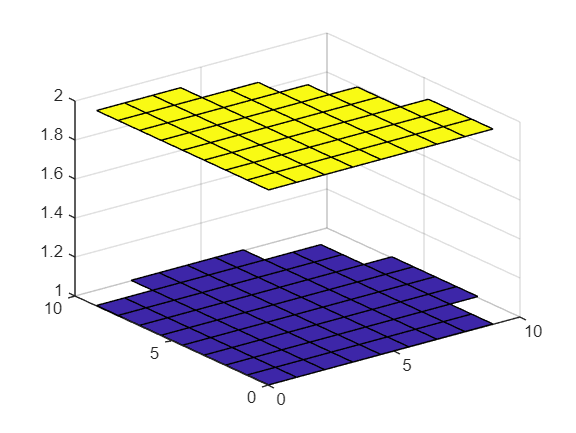


figure;
surf(xl, yl, zlb);
hold on;
surf(xl, yl, zlt);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Helper functions for defining the plate boundaries